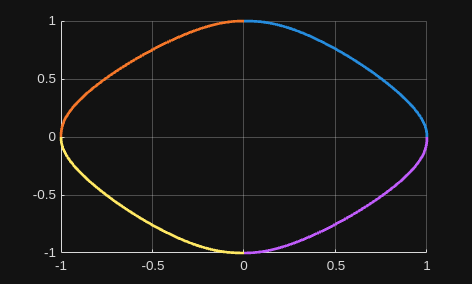

px = [1 0 -1 0]; %cos
py = [0 1 0 -1]; %sin
pz = [0 1 2 3]; %sin
p = [px;py;pz];

dpx = [0 -1 0 1]; %-sin
dpy = [1 0 -1 0]; %cos
dpz = [1 1 1 -1]; %cos
dp = [dpx;dpy;dpz];

ddpx = [-1 0 1 0]; %-cos
ddpy = [0 -1 0 1]; %-sin
ddpz = [-1 0 0 -1]; %-sin
ddp = [ddpx;ddpy;ddpz];

f = PathPlanning(p,dp,ddp); %returns function
N = size(p,2);
n = size(p,1);

%inserts numbers in f to get 3rd order tensor of points
s = 0:0.01:1;
f_ = zeros(1,size(p,2),length(s));
for j = 1:n
    g = f{j};
    for i = 1:length(s)
        f_(j,:,i) = g(s(i));
    end
end


hold on
for k = 1:size(f_,2)
    pos = f_(:,k,:);
    plot3(pos(1,:),pos(2,:),pos(3,:),'LineWidth', 2)
end

grid on